# Power Spectrum of the Sea Level at Grand Isle

Let us now calculate the Power spectrum of an actual time series. We start with sea level (in mm, referred to grobal benchmark) at Grand Isle, and with the simple 'Periodogram estimation' method we have seen so far. This may not be the most accurate way to estimate the spectrum but for now - and for understanding the big picture, it will do.

***Author: Annalisa Molini***

***Last updated: Oct 19, 2022***

## Loading data

load("GrandIsle_TG_and_Vicksburg_Index.mat");
X=M(1:end); % Select Sea Level at Grand Isle
L=size(X,1);  % Length of signal [Number of monthly samples]

## Signal Sampling and Duration

Let us first define the sampling and duration of our signal:

Fs = 12;              % Sampling frequency [in years^-1] >> 12 samples for year equate a monthly sampling frequency
Nyq=Fs/2;             % Nyquist frequency [in years^-1]  
T = 1/Fs;             % Sampling period [in years]   
% We do not need a time vector in this case because we have already have a
% years vector t 

Let us now plot the signal in the time domain:

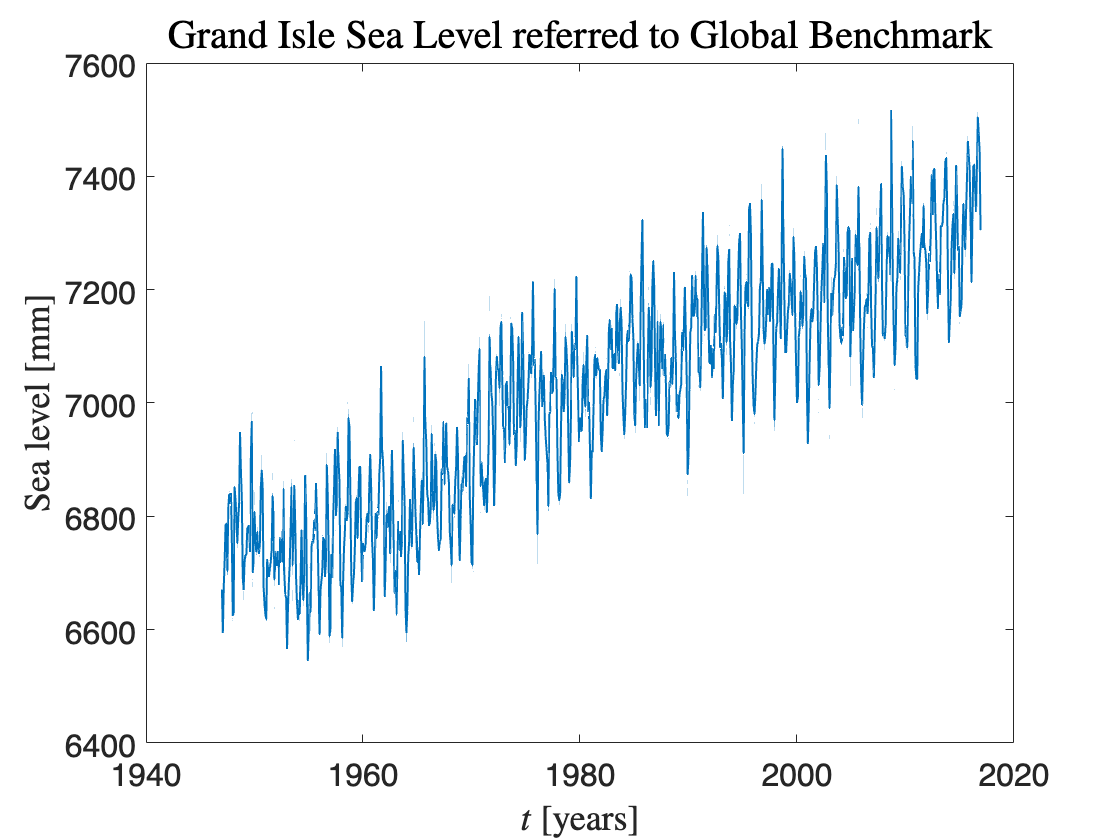

figure;
hx=plot(t,X);
set(hx,'linewidth', 1);
set(gca,'FontSize',16);

% Axex labels
xlabel("$t$ [years]","FontSize",18,'Interpreter','latex')
ylabel("Sea level [mm]","FontSize",18,'Interpreter','latex'); % check units
title("Grand Isle Sea Level referred to Global Benchmark","FontSize",20,'Interpreter','latex')

This signal has a clear incresing trend, and we know that we should not apply the Fourier transform to non stationary signals. But let us try to calculate the FFT in any case for "demonstrational" purposes. We first plot it in linear scale...

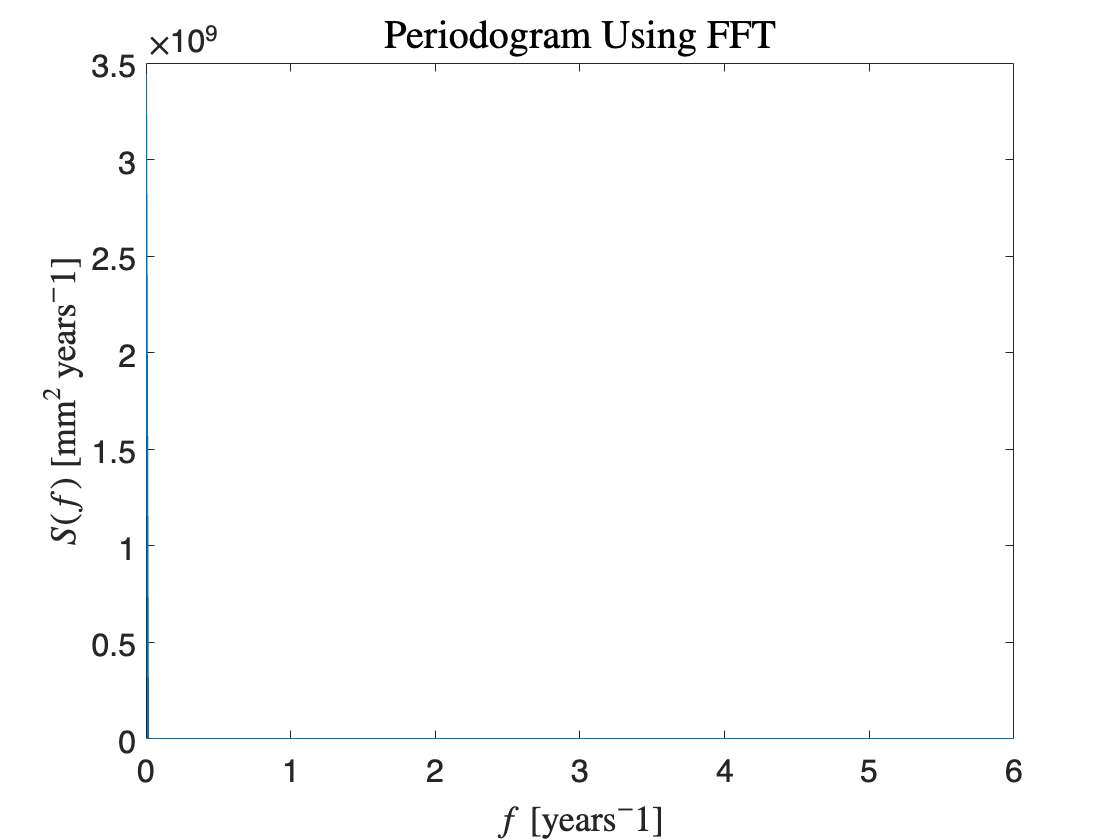

Y = fft(X);
S = (1/(Fs*L)) * abs(Y).^2; % Dividing by L and Fs we obtain a Power (Energy per unit of time) per unit of frequency
S1 = S(1:L/2+1); 
S1(2:end-1) = 2*S1(2:end-1);
f = Fs*(0:(L/2))/L; 
Period=1./f;

figure;
hs=plot(f,S1);
set(hs,'linewidth', 1);
set(gca,'FontSize',16);

title("Periodogram Using FFT","FontSize",20,'Interpreter','latex');
xlabel("$f$ [years$^-1$]","FontSize",18,'Interpreter','latex');
ylabel("$S(f)$ [mm$^2$ years$^-1$]","FontSize",18,'Interpreter','latex');

And then in semilog (log along y):

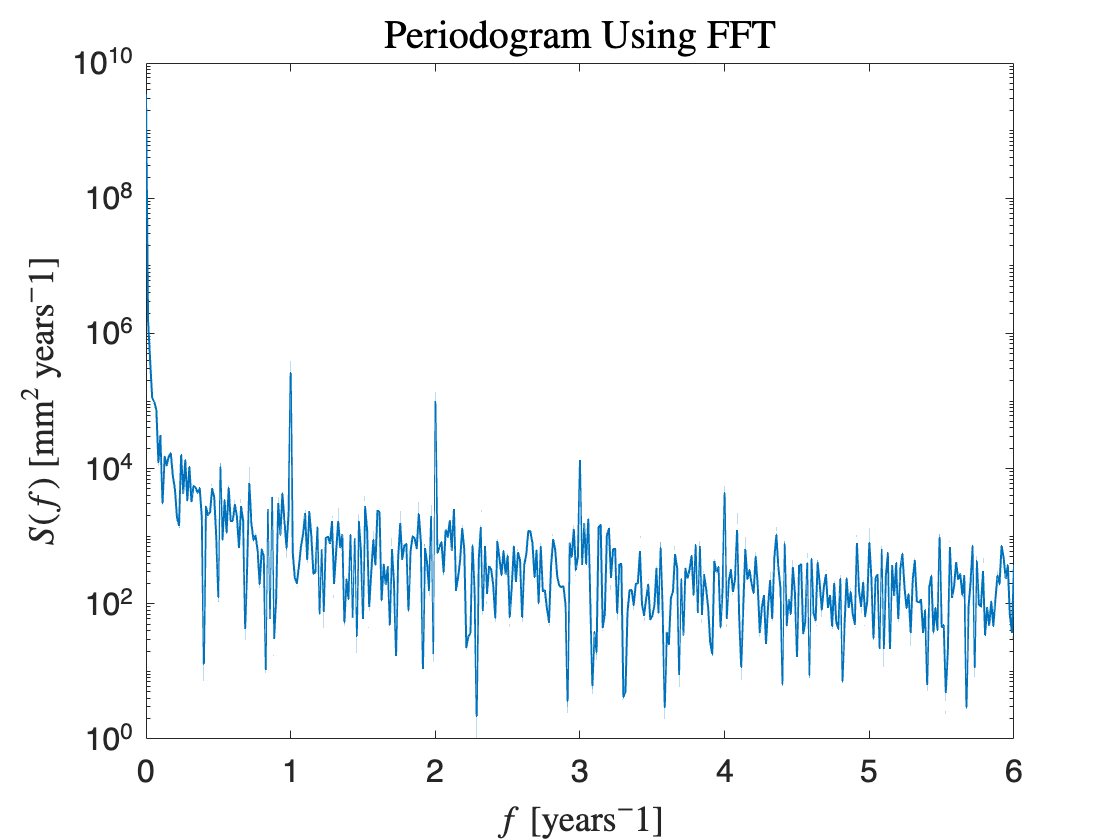

figure;
hs=semilogy(f,S1);
set(hs,'linewidth', 1);
set(gca,'FontSize',16);
%set(gca,'FontSize',16,'XDir','reverse');

title("Periodogram Using FFT","FontSize",20,'Interpreter','latex');
xlabel("$f$ [years$^-1$]","FontSize",18,'Interpreter','latex');
ylabel("$S(f)$ [mm$^2$ years$^-1$]","FontSize",18,'Interpreter','latex');

The high power at the lowest frequency is obviously due to the trend. Let us now try to detrend:

p=polyfit(t,X,1);
Xl=polyval(p,t);
Xnew=X-Xl;

p(1)

ans = 9.1083

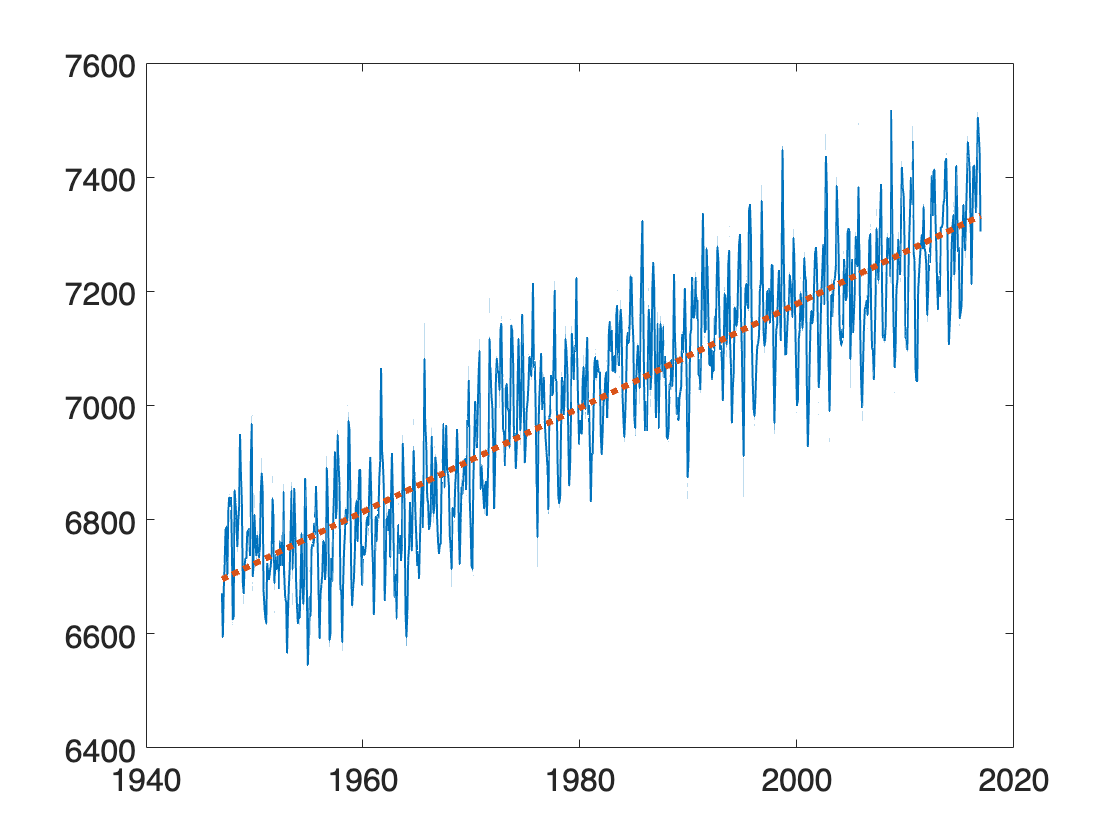

figure;
hx=plot(t,X);
set(hx,'linewidth', 1);
set(gca,'FontSize',16);
hold on
hl=plot(t, Xl);
set(hl,'linewidth', 3,'linestyle',':');
set(gca,'FontSize',16);
hold off

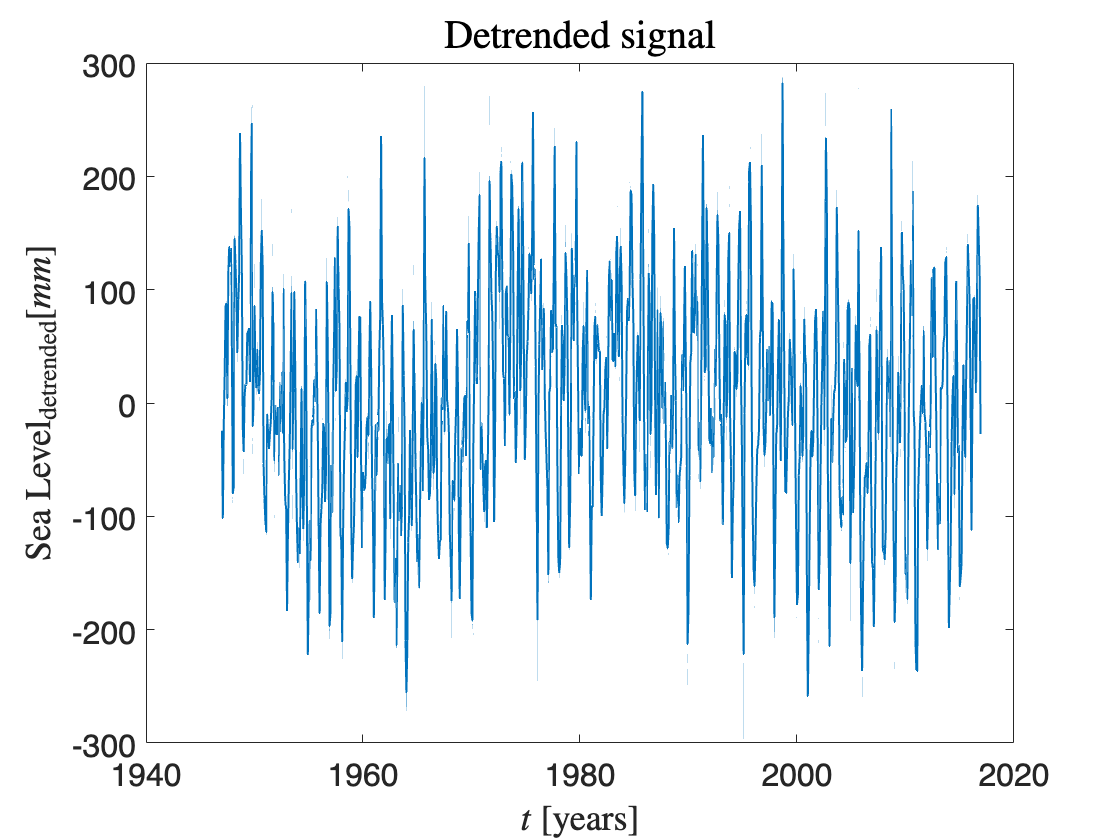

figure;
hnew=plot(t,Xnew);
set(hnew,'linewidth', 1);
set(gca,'FontSize',16);

title("Detrended signal","FontSize",20,'Interpreter','latex');
xlabel("$t$ [years]","FontSize",18,'Interpreter','latex');
ylabel("Sea Level$_{\rm{detrended}} [mm]$","FontSize",18,'Interpreter','latex');

and recalculate the spectrum:

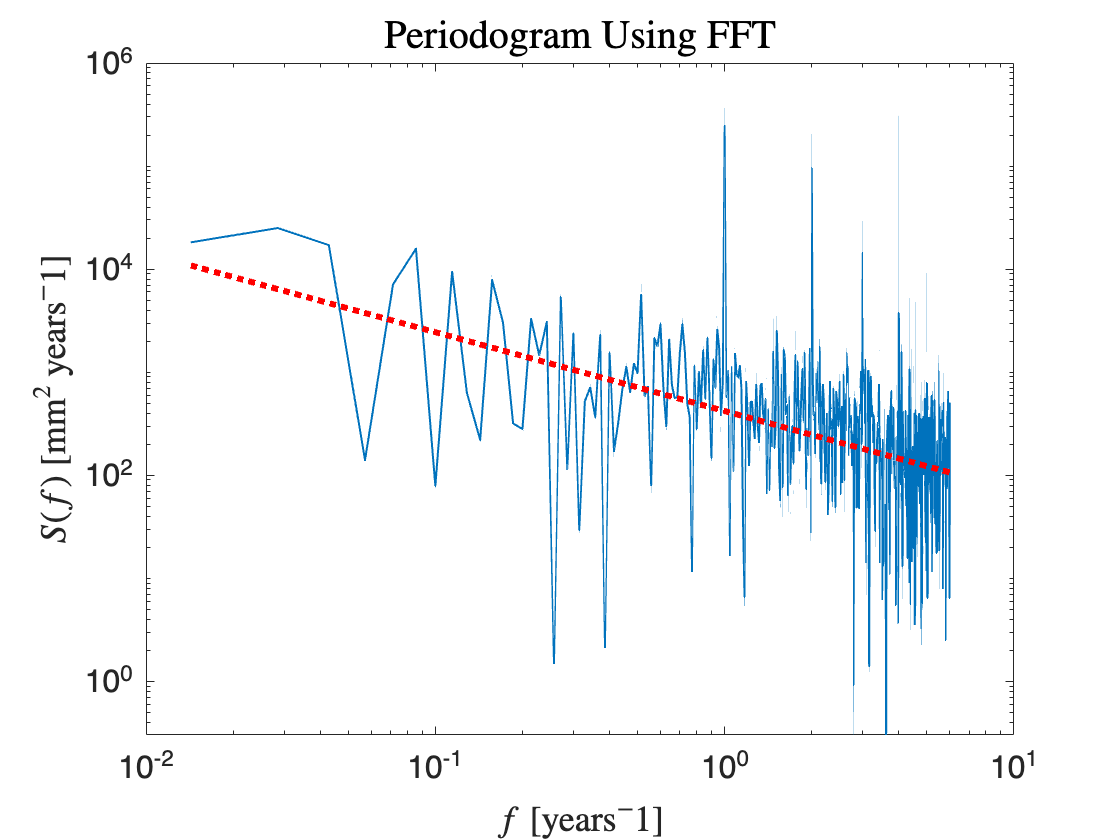

Ynew = fft(Xnew);
S = (1/(Fs*L)) * abs(Ynew).^2; % Dividing by L and Fs we obtain a Power (Energy per unit of time) per unit of frequency
Snew = S(1:L/2+1); % we keep the 0 off in this case, we will see later why
Snew(2:end-1) = 2*Snew(2:end-1);

figure;
hnew=loglog(f(2:end),Snew(2:end));
set(hnew,'linewidth', 1);
set(gca,'FontSize',16);

p2 = polyfit(log10(f(2:end)),log10(Snew(2:end)),1);
y2=10^(p2(2))*f.^(p2(1)); 

hold on
hpl=loglog(f(2:end),y2(2:end));
set(hpl,'linewidth', 3,'color','r','linestyle',':');
hold off

title("Periodogram Using FFT","FontSize",20,'Interpreter','latex');
xlabel("$f$ [years$^-1$]","FontSize",18,'Interpreter','latex');
ylabel("$S(f)$ [mm$^2$ years$^-1$]","FontSize",18,'Interpreter','latex');

 This is not 'super-orthodox' but let us try to filter it out the seasonal cycle using Fourier (first and second harmonics):

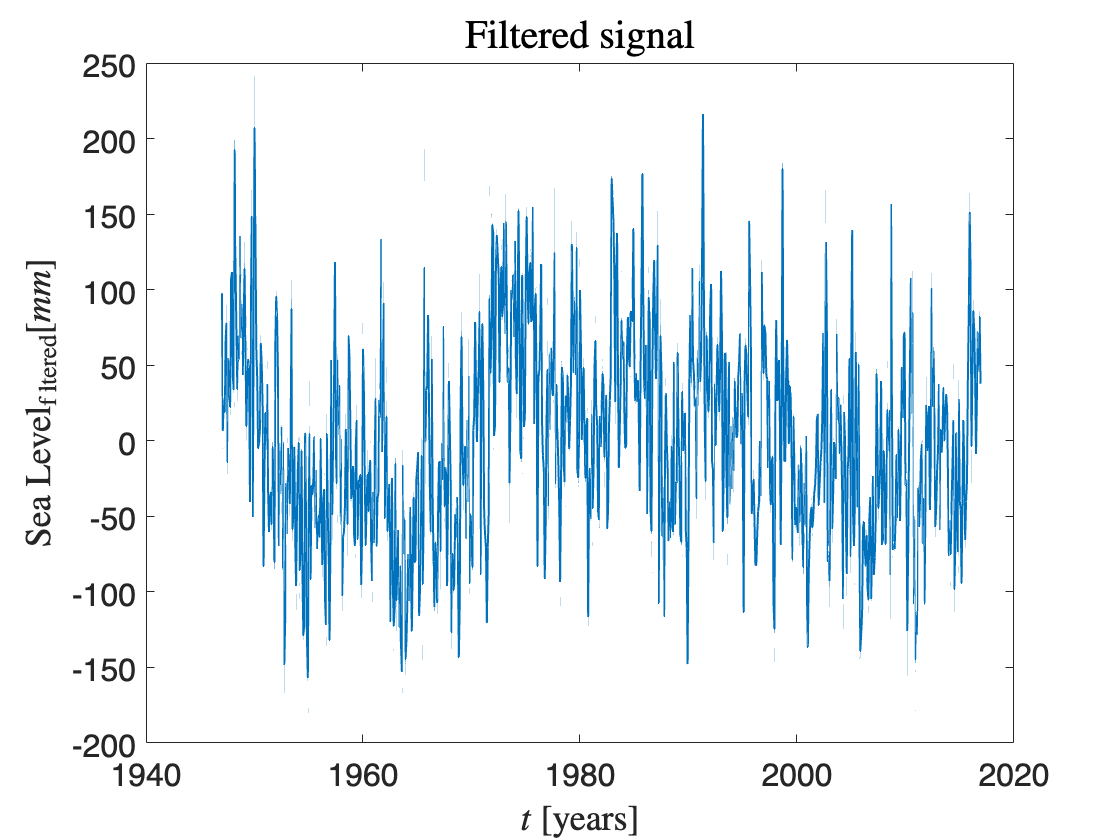

% Filter the low-amplitude component of the spectrum
Thrs=90000/2; %remember to divide the threshold by two since you are referring to the 1 sided spectrum
Yi=Ynew;
Yi(S>Thrs)=1;

% Calculate the inverse Fourier transform of the filtered-fft
Xnew2=ifft(Yi);

%Plot the filtered signal 

figure;
hxx=plot(t,Xnew2);
set(hxx,'linewidth', 1);
set(gca,'FontSize',16);
title("Filtered signal","FontSize",20,'Interpreter','latex');
xlabel("$t$ [years]","FontSize",18,'Interpreter','latex');
ylabel("Sea Level$_{\rm{filtered}} [mm]$","FontSize",18,'Interpreter','latex');

And let us calculate the spectrum again:

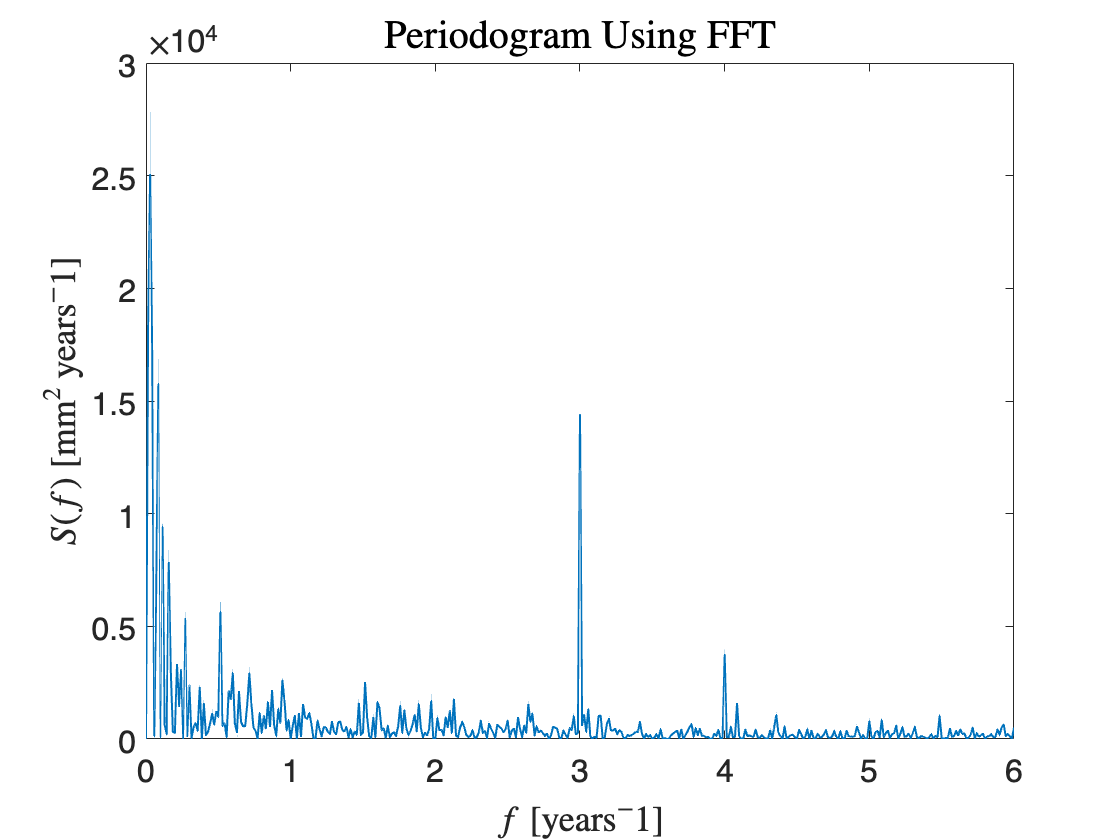

Yf = fft(Xnew2);
S = (1/(Fs*L)) * abs(Yf).^2; % Dividing by L and Fs we obtain a Power (Energy per unit of time) per unit of frequency
Sf = S(1:L/2+1); % we keep the 0 off in this case, we will see later why
Sf(2:end-1) = 2*Sf(2:end-1);

figure;
hsf=plot(f,Sf); %,'MarkerIndices'1:10:length(f), 'Marker','o'
set(gca,'FontSize',16);
set(hsf,'linewidth', 1);

title("Periodogram Using FFT","FontSize",20,'Interpreter','latex');
xlabel("$f$ [years$^-1$]","FontSize",18,'Interpreter','latex');
ylabel("$S(f)$ [mm$^2$ years$^-1$]","FontSize",18,'Interpreter','latex');

Let us focus on low frequencies. There are in particular two peaks, with characteristic period ~2 years and ~8years that are interesting...

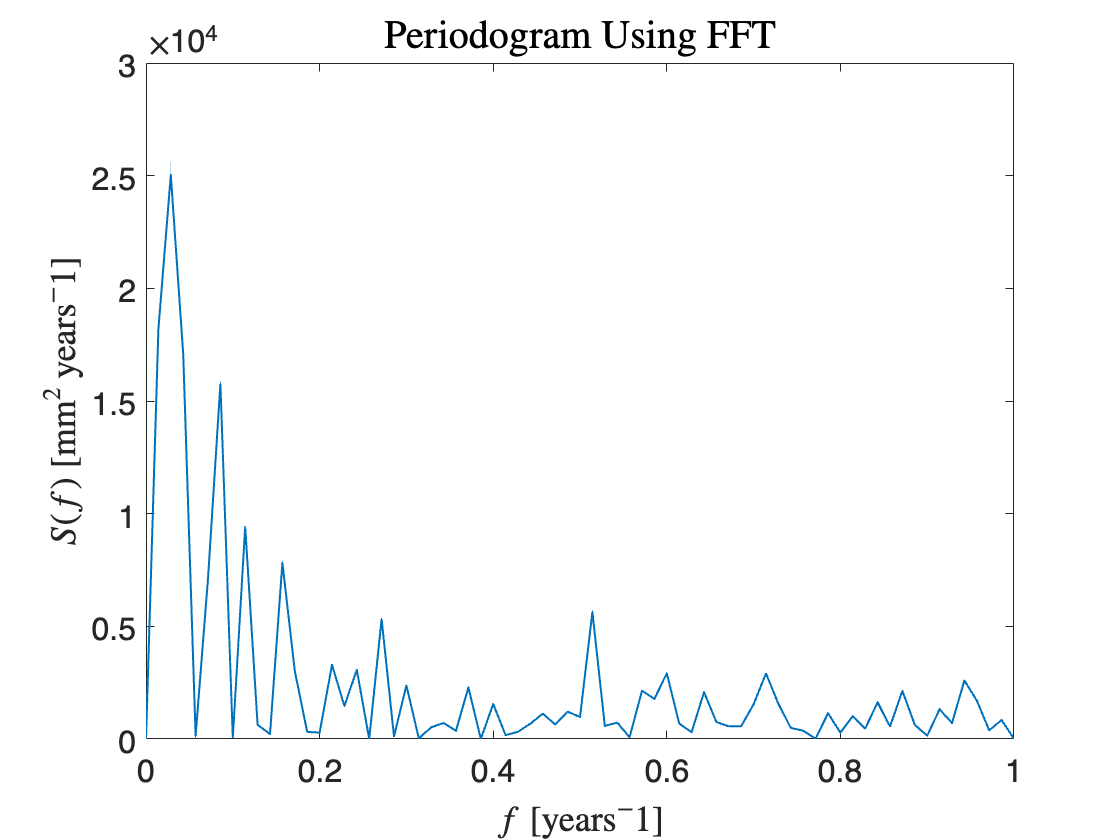

xlim([0 1]);